clear;
clc;

% Parámetros de la órbita inicial
mu = 3.986004418e14;      % Parámetro gravitacional terrestre   [m³/s²]
J2 = 1.082635854e-3;      % Segundo coeficiente armónico zonal  [-]
J3 = -2.532435346e-6;     % Tercer coeficiente armónico zonal   [-]
R  = 6378.137e3;          % Radio terrestre ecuatorial          [m]
a = R + 1400e3;           % Semieje mayor                       [m]
    n = sqrt(mu ./ a.^3); % Movimiento medio                    [rad/s]
e = 0;                    % Excentricidad                       [-]
INC     = deg2rad(90);    % Inclinacion                         [rad]
Omega   = deg2rad(0);     % Ascensión recta del nodo ascendente [rad]
omega   = deg2rad(0);     % Argumento del perigeo               [rad]
theta_0 = deg2rad(0);     % Anomalía verdadera inicial          [rad]

% Conversión de elementos orbitales a ECI
[posECI, velECI] = OE2ECI(mu, a, e, INC, Omega, omega, theta_0);
X0I = [posECI; velECI];
X0  = [0; 0; 0; 0; 0; 0];

%% Simulaciones
iterations = 100;
maxTime = 4*2*pi/n;
timeStamps = 1:100:maxTime;
meanTime_cowell  = zeros(length(timeStamps),1);
meanTime_general = zeros(length(timeStamps),1);
meanTime_hodei   = zeros(length(timeStamps),1);
meanSimulationTime = zeros(length(timeStamps),1);

opts = odeset('RelTol', 1e-12, 'AbsTol', 1e-5);
for i = 1:length(timeStamps)
    timeSpan = timeStamps(i);
    times_cowell  = zeros(iterations,1);
    times_general = zeros(iterations,1);
    times_hodei   = zeros(iterations,1);

    for k = 1:iterations
        tic;
        cowellZonals(X0I, [0 timeSpan], mu, R, [J2; J3; 0; 0; 0], opts);
        times_cowell(k) = toc;

        tic;
        computeGeneralSolutionRelative(J2, 0, R, a, e, INC, Omega, omega, theta_0, X0, n, timeSpan); 
        times_general(k) = toc;

        tic;
        hodeiMotion([0 timeSpan], X0I, mu, R, 0, J2, opts);
        times_hodei(k) = toc;
    end
    meanTime_cowell(i)  = mean(times_cowell);
    meanTime_general(i) = mean(times_general);
    meanTime_hodei(i)   = mean(times_hodei);
end

%% Gráfica de comparación
figure;
hold on;
plot(timeStamps/3600, meanTime_cowell*1e3, '-', 'Color', [0 0 0], 'LineWidth', 1.5);
plot(timeStamps/3600, meanTime_hodei*1e3, '-', 'Color', 1 - [0.56 0.07 0.65],  'LineWidth', 1.5);
plot(timeStamps/3600, meanTime_general*1e3, '-', 'Color', [0.56 0.07 0.65],  'LineWidth', 1.5);
xlabel('Tiempo de simulaci\''on (h)', 'Interpreter', 'latex');
ylabel('Tiempo de c\''omputo (ms)', 'Interpreter', 'latex');
title('\bf{Comparaci\''on de tiempos de simulaci\''on}', 'Interpreter', 'latex');
legend({'Cowell Method', 'Radial Intermediary', 'Revised K\''echichian'}, ...
    'Interpreter', 'latex', 'Location', 'northoutside', 'Orientation', 'horizontal');
grid on;
xlim([min(timeStamps/3600), max(timeStamps/3600)]);
hold off;

% Preparar BaseZoom
bz = BaseZoom(gca); % le pasas el objeto axes
bz.run();           % ejecuta la interacción

Use the left mouse button to draw a rectangle.
for the sub axes...
Use the left mouse button to draw a rectangle.
for the zoomed area...


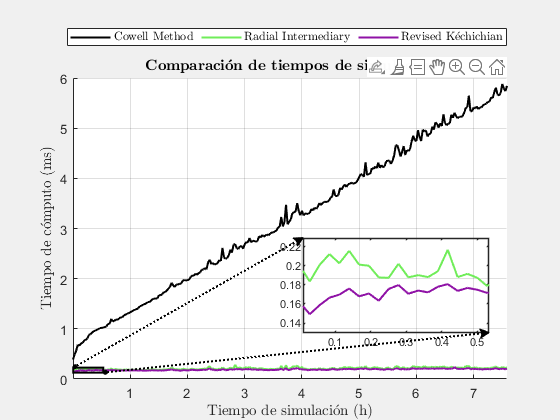


% Guardar figura en la carpeta 'figuras'
if ~exist('figuras', 'dir')
    mkdir('figuras');
end
saveas(gcf, fullfile('figuras', 'tiempos.svg'));


% Calcular tiempo medio de ejecución
analyticalMeanTime = mean(meanTime_general*1e3)

analyticalMeanTime = 0.1886

intermediaryMeanTime = mean(meanTime_hodei*1e3)

intermediaryMeanTime = 0.2121